# The Quantum Mouse - Part III

## Fully Deterministic Perception-Action Cycle

[*Matthias Wolff*](https://www.b-tu.de/en/fg-kommunikationstechnik/team/staff/prof-dr-ing-habil-matthias-wolff)

[BTU Cottbus-Senftenberg](https://www.b-tu.de/en/), [Chair of Communications Engineering](https://www.b-tu.de/en/fg-kommunikationstechnik)

fock.addFockBoxPaths();

## 1   Perception-Action Cycle

We consider a mouse agent $\mathcal{A}$ which is interconnected with a $N\times M$ maze world $\mathcal{W}$ it lives in by a *perception-action cycle* shown in Fig. 1.

**Fig. 1: Perception-action cycle between mouse and maze**

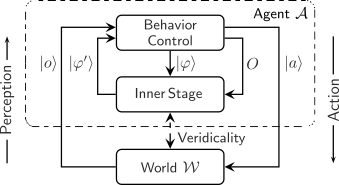

The mouse can input *actions*

        
$$|a\rangle \in\{|\!+\!X\rangle,|0X\rangle,|\!-\!X\rangle\}\otimes\{|\!+\!Y\rangle,|0Y\rangle,|\!-\!Y\rangle\}$$


into the world. The world, in turn, will output *observations*

        
$$|o\rangle\in\mathcal{H}_X\otimes\mathcal{H}_Y\otimes\mathcal{H}_C\otimes\mathcal{H}_G$$


where $\mathcal{H}_\cdot$ denotes Hilbert spaces

        $\mathcal{H}_X = \mbox{span}\big(|1_X\rangle, \ldots, |N_X\rangle\big)$   - x-coordinate space,

        $\mathcal{H}_Y = \mbox{span}\big(|1_Y\rangle, \ldots, |M_Y\rangle\big)$   - y-coordinate space,

        $\mathcal{H}_C = \mbox{span}\big(|0_C\rangle, |1_C\rangle\big)$          - cheese space, and

        $\mathcal{H}_G = \mbox{span}\big(|0_G\rangle, |1_G\rangle\big)$          - water space.

Throughout this example we assume a fully deterministic stetting, i.e. there is no sensor or actuator noise and no randmoness in the world.

**1.1   Mouse and Maze**

First, we create a maze world (Fig. 2):

world = Maze();
world.mmp.setCamPos(-5,-18,23);
for x=1:3
  for y=1:3
    world.addPlace(x,y);
  end
end
for i=1:3
  world.addWall(i,1,'S');
  world.addWall(i,3,'N');
  world.addWall(1,i,'W');
  world.addWall(3,i,'E');
  world.addWater(3,i);
end
world.addWall(2,2,'W');
world.addWall(2,2,'N');
world.addWall(3,2,'N');
world.addCheese(3,3);
title(world.mmp.ax,"Figure 2 - Maze world");

The we create a mouse agent

mouse = Agent.createMouse();
mouse.mmp.setCamPos(-5,-18,23);
title(mouse.mmp.ax,"Figure 2 - Inner stage of mouse agent");

and equip it with some (instinctive) knowledge, here four basic movement actions $|a_E\rangle=|{\!+\!}_X\,0_Y\rangle$, $|a_W\rangle=|{\!-\!}_X\,0_Y\rangle$, $|a_N\rangle=|0_X\,{\!+\!}_Y\rangle$, and $|a_N\rangle=|0_X\,{\!-\!}_Y\rangle$:

mouse.addAction('E',fockobj.bket('+X§0Y'));
mouse.addAction('W',fockobj.bket('-X§0Y'));
mouse.addAction('N',fockobj.bket('0X§+Y'));
mouse.addAction('S',fockobj.bket('0X§-Y'));

Finally, we set the mouse into the maze at location $(1,1)$

world.addAgent(mouse,1,1);

**1.2   Exploring the World**

[**TODO:** ...]

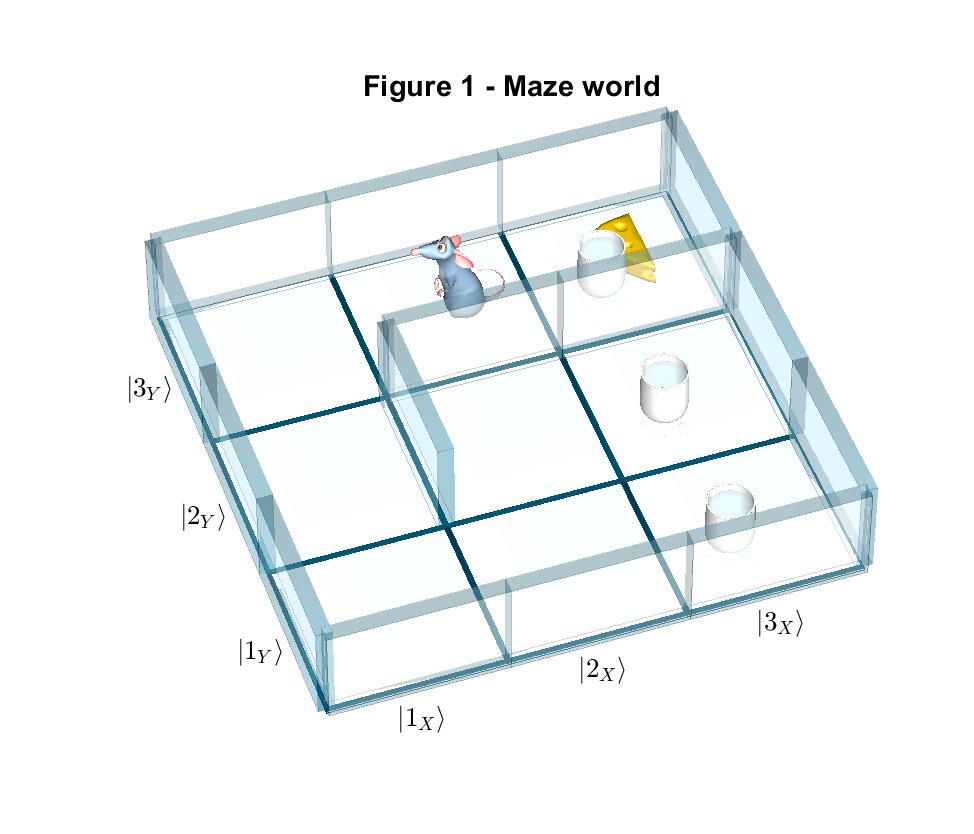

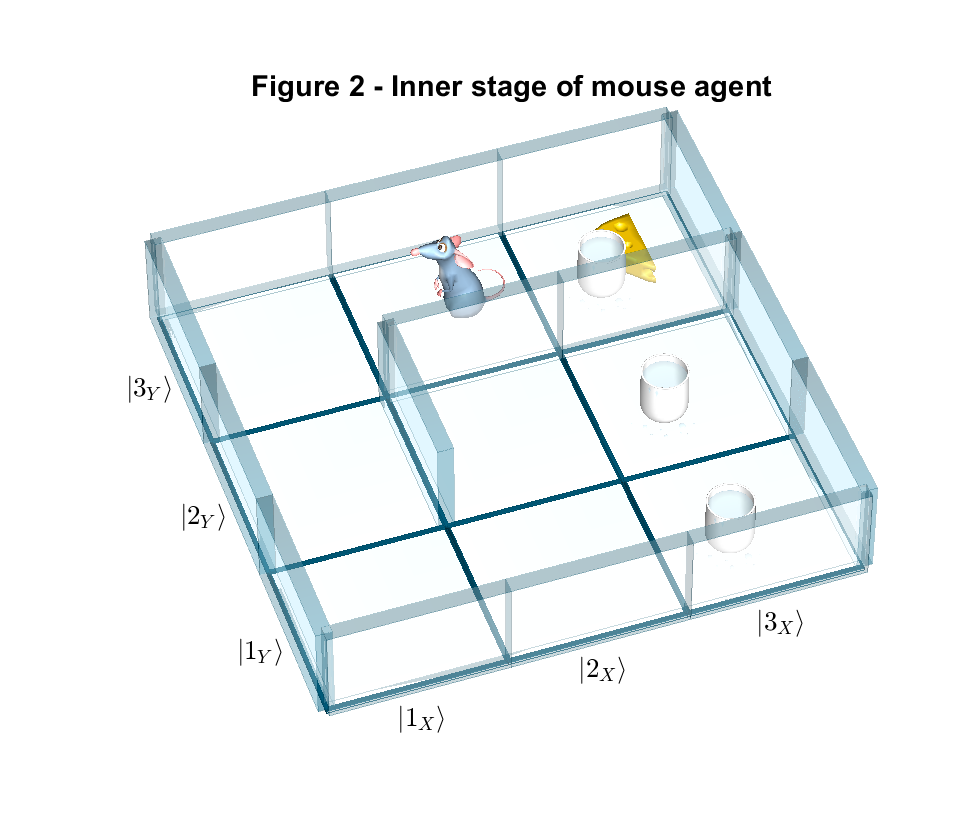

set(world.mmp.ax.Parent,'Visible','on','WindowStyle','normal');
set(mouse.mmp.ax.Parent,'Visible','on','WindowStyle','normal');
set(world.mmp.ax.Parent,'OuterPosition',[0,100,500,500]);
set(mouse.mmp.ax.Parent,'OuterPosition',[500,100,500,500]);

%mouse.rexplore(1000);
mouse.sexplore(1:3,1:3);

**1.3  The Result of Exploration**

[**TODO:** ...]

## 2   Operators on the Inner Stage

[**TODO:** ...]

PV   = mouse.getVeridicalityProj(); disp(PV);                                   % Veridicality projector

___________________________________________________________


Some operators and projectors:



  fockobj

    Name: PV 
    Type: linear operator 

    (1X⊗1Y⊗0C⊗0G,1X⊗1Y⊗0C⊗0G)	1.000000
    (1X⊗2Y⊗0C⊗0G,1X⊗2Y⊗0C⊗0G)	1.000000
    (1X⊗3Y⊗0C⊗0G,1X⊗3Y⊗0C⊗0G)	1.000000
    (2X⊗1Y⊗0C⊗0G,2X⊗1Y⊗0C⊗0G)	1.000000
    (2X⊗2Y⊗0C⊗0G,2X⊗2Y⊗0C⊗0G)	1.000000
    (2X⊗3Y⊗0C⊗0G,2X⊗3Y⊗0C⊗0G)	1.000000
    (3X⊗1Y⊗0C⊗1G,3X⊗1Y⊗0C⊗1G)	1.000000
    (3X⊗2Y⊗0C⊗1G,3X⊗2Y⊗0C⊗1G)	1.000000
    (3X⊗3Y⊗1C⊗1G,3X⊗3Y⊗1C⊗1G)	1.000000


Fxy  = mouse.getFocusOp('XY');      disp(Fxy);                                  % Focus-on-XY operator

  fockobj

    Name: F(XY) 
    Type: linear operator 

    (1X⊗1Y,1X⊗1Y⊗0C⊗0G) 	1.000000
    (1X⊗1Y,1X⊗1Y⊗0C⊗1G) 	1.000000
    (1X⊗1Y,1X⊗1Y⊗1C⊗0G) 	1.000000
    (1X⊗1Y,1X⊗1Y⊗1C⊗1G) 	1.000000
    (1X⊗2Y,1X⊗2Y⊗0C⊗0G) 	1.000000
    (1X⊗2Y,1X⊗2Y⊗0C⊗1G) 	1.000000
    (1X⊗2Y,1X⊗2Y⊗1C⊗0G) 	1.000000
    (1X⊗2Y,1X⊗2Y⊗1C⊗1G) 	1.000000
    (1X⊗3Y,1X⊗3Y⊗0C⊗0G) 	1.000000
    (1X⊗3Y,1X⊗3Y⊗0C⊗1G) 	1.000000
    (1X⊗3Y,1X⊗3Y⊗1C⊗0G) 	1.000000
    (1X⊗3Y,1X⊗3Y⊗1C⊗1G) 	1.000000
    (2X⊗1Y,2X⊗1Y⊗0C⊗0G) 	1.000000
    (2X⊗1Y,2X⊗1Y⊗0C⊗1G) 	1.000000
    (2X⊗1Y,2X⊗1Y⊗1C⊗0G) 	1.000000
    (2X⊗1Y,2X⊗1Y⊗1C⊗1G) 	1.000000
    (2X⊗2Y,2X⊗2Y⊗0C⊗0G) 	1.000000
    (2X⊗2Y,2X⊗2Y⊗0C⊗1G) 	1.000000
    (2X⊗2Y,2X⊗2Y⊗1C⊗0G) 	1.000000
    (2X⊗2Y,2X⊗2Y⊗1C⊗1G) 	1.000000
    (2X⊗3Y,2X⊗3Y⊗0C⊗0G) 	1.000000
    (2X⊗3Y,2X⊗3Y⊗0C⊗1G) 	1.000000
    (2X⊗3Y,2X⊗3Y⊗1C⊗0G) 	1.000000
    (2X⊗3Y,2X⊗3Y⊗1C⊗1G) 	1.000000
    (3X⊗1Y,3X⊗1Y⊗0C⊗0G) 	1.000

UGxy = mouse.getUnfocusOp('XY');    disp(UGxy);                                 % Generic unfocus-from-XY operator

  fockobj

    Name: Ug(XY) 
    Type: linear operator 

    (1X⊗1Y⊗0C⊗0G,1X⊗1Y) 	1.000000
    (1X⊗1Y⊗0C⊗1G,1X⊗1Y) 	1.000000
    (1X⊗1Y⊗1C⊗0G,1X⊗1Y) 	1.000000
    (1X⊗1Y⊗1C⊗1G,1X⊗1Y) 	1.000000
    (1X⊗2Y⊗0C⊗0G,1X⊗2Y) 	1.000000
    (1X⊗2Y⊗0C⊗1G,1X⊗2Y) 	1.000000
    (1X⊗2Y⊗1C⊗0G,1X⊗2Y) 	1.000000
    (1X⊗2Y⊗1C⊗1G,1X⊗2Y) 	1.000000
    (1X⊗3Y⊗0C⊗0G,1X⊗3Y) 	1.000000
    (1X⊗3Y⊗0C⊗1G,1X⊗3Y) 	1.000000
    (1X⊗3Y⊗1C⊗0G,1X⊗3Y) 	1.000000
    (1X⊗3Y⊗1C⊗1G,1X⊗3Y) 	1.000000
    (2X⊗1Y⊗0C⊗0G,2X⊗1Y) 	1.000000
    (2X⊗1Y⊗0C⊗1G,2X⊗1Y) 	1.000000
    (2X⊗1Y⊗1C⊗0G,2X⊗1Y) 	1.000000
    (2X⊗1Y⊗1C⊗1G,2X⊗1Y) 	1.000000
    (2X⊗2Y⊗0C⊗0G,2X⊗2Y) 	1.000000
    (2X⊗2Y⊗0C⊗1G,2X⊗2Y) 	1.000000
    (2X⊗2Y⊗1C⊗0G,2X⊗2Y) 	1.000000
    (2X⊗2Y⊗1C⊗1G,2X⊗2Y) 	1.000000
    (2X⊗3Y⊗0C⊗0G,2X⊗3Y) 	1.000000
    (2X⊗3Y⊗0C⊗1G,2X⊗3Y) 	1.000000
    (2X⊗3Y⊗1C⊗0G,2X⊗3Y) 	1.000000
    (2X⊗3Y⊗1C⊗1G,2X⊗3Y) 	1.000000
    (3X⊗1Y⊗0C⊗0G,3X⊗1Y) 	1.00

Uxy  = PV*UGxy; Uxy.name='U(XY)';   disp(Uxy);                                  % Veridical unfocus-from-XY operator

  fockobj

    Name: U(XY) 
    Type: linear operator 

    (1X⊗1Y⊗0C⊗0G,1X⊗1Y) 	1.000000
    (1X⊗2Y⊗0C⊗0G,1X⊗2Y) 	1.000000
    (1X⊗3Y⊗0C⊗0G,1X⊗3Y) 	1.000000
    (2X⊗1Y⊗0C⊗0G,2X⊗1Y) 	1.000000
    (2X⊗2Y⊗0C⊗0G,2X⊗2Y) 	1.000000
    (2X⊗3Y⊗0C⊗0G,2X⊗3Y) 	1.000000
    (3X⊗1Y⊗0C⊗1G,3X⊗1Y) 	1.000000
    (3X⊗2Y⊗0C⊗1G,3X⊗2Y) 	1.000000
    (3X⊗3Y⊗1C⊗1G,3X⊗3Y) 	1.000000


PL11 = mouse.getLocationProj(1,1);  disp(PL11);                                 % Projector on location (1,1)

  fockobj

    Name: PL(1,1,-1,-1) 
    Type: linear operator 

    (1X⊗1Y⊗0C⊗0G,1X⊗1Y⊗0C⊗0G)	1.000000
    (1X⊗1Y⊗0C⊗1G,1X⊗1Y⊗0C⊗1G)	1.000000
    (1X⊗1Y⊗1C⊗0G,1X⊗1Y⊗1C⊗0G)	1.000000
    (1X⊗1Y⊗1C⊗1G,1X⊗1Y⊗1C⊗1G)	1.000000
